AUDIOPATH='audioFiles\';
info = audioinfo(fullfile(AUDIOPATH, 'a_1_men1.wav'))

info = struct with fields:
             Filename: 'C:\Users\Tape\OneDrive - Akademia Górniczo-Hutnicza im. Stanisława Staszica w Krakowie\Desktop\Interfejsy multimodalne\lab5\SPEECH_files\audioFiles\a_1_men1.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 44100
         TotalSamples: 43520
             Duration: 0.9868
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


[y,Fs] = audioread(fullfile(AUDIOPATH, 'a_1_men1.wav'));
deviceWriter = audioDeviceWriter(Fs);
deviceWriter(y)

ans = uint32
0

Pierwsza Harmoniczna: 121.599

Druga: 242.185

Trzecia: 363.784

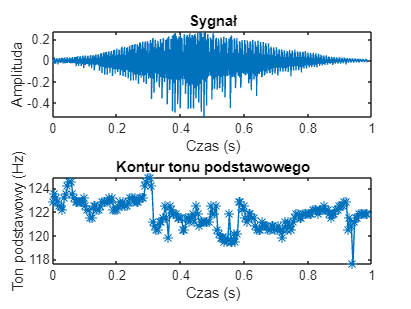

figure;
subplot(2,1,1)
plot(t1, y2)
ylabel('Amplituda')
xlabel('Czas (s)')
title('Sygnał')
subplot(2,1,2)
plot(timeVectorPitch,f0,'-*')
ylabel('Ton podstawowy (Hz)')
xlabel('Czas (s)')
title('Kontur tonu podstawowego')


disp(['Średnia wartość tonu podstawowego dla całego sygnału = ' num2str(mean(f0)) ' [Hz]'])

Średnia wartość tonu podstawowego dla całego sygnału = 121.8408 [Hz]


    Średnia jest podobna do częstotliwości tonu krtaniowego

%% (4) Estymacja formantów LPC
% Zapoznaj się z funkcją w pliku "estimate_formants.m"
formants = estimate_formants(y2, Fs); 
% wybór 3 pierwszych formantów
sprintf('Formanty : F1=%5.2f Hz, F2=%5.2f Hz,  F3=%5.2f Hz', formants(1:3))

ans = 'Formanty : F1=681.48 Hz, F2=1236.66 Hz,  F3=2704.08 Hz'

Formanty to wielokrotności około 5.5 - 7 razy w stosunku do częstotliwości tonu podstawowego, ale może to być przypadek.

Własny plik audio

AUDIOPATH='audioFiles\';
info = audioinfo(fullfile(AUDIOPATH, 'a_1_me.wav'))

info = struct with fields:
             Filename: 'C:\Users\krzys\Desktop\InterfejsyMultimodalne\lab5\SPEECH_files\audioFiles\a_1_me.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 44100
         TotalSamples: 51712
             Duration: 1.1726
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


[y,Fs] = audioread(fullfile(AUDIOPATH, 'a_1_me.wav'));
deviceWriter = audioDeviceWriter(Fs);
deviceWriter(y)

ans = uint32
0

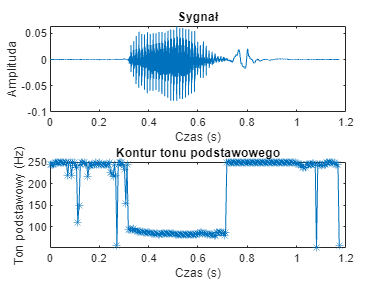


figure;
subplot(2,1,1)
plot(t1, y2)
ylabel('Amplituda')
xlabel('Czas (s)')
title('Sygnał')
subplot(2,1,2)
plot(timeVectorPitch,f0,'-*')
ylabel('Ton podstawowy (Hz)')
xlabel('Czas (s)')
title('Kontur tonu podstawowego')


disp(['Średnia wartość tonu podstawowego dla całego sygnału = ' num2str(mean(f0)) ' [Hz]'])

Średnia wartość tonu podstawowego dla całego sygnału = 187.4156 [Hz]



%% (4) Estymacja formantów LPC
% Zapoznaj się z funkcją w pliku "estimate_formants.m"
formants = estimate_formants(y2, Fs); 
% wybór 3 pierwszych formantów
sprintf('Formanty : F1=%5.2f Hz, F2=%5.2f Hz,  F3=%5.2f Hz', formants(1:3))

ans = 'Formanty : F1=750.16 Hz, F2=1145.63 Hz,  F3=2559.91 Hz'

Część III

głoski

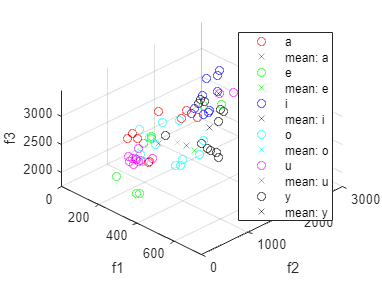

%% (2) Analiza i wizualizacja danych
uWovels = unique(vowelClass);           % unikalne nazwy samogłosek
nrOfVowels = length(uWovels);           % liczba samogłosek


colors1='rgbcmky';
figure;
hold on
% pętla po kolejnych samogłoskach
legendstr={};k=1;
for i=1:nrOfVowels
    % wybór elementów, wektor logiczny
    select1 = strcmp(vowelClass,uWovels(i));            
    
    % UZUPELNIJ_1
    % wybór elementów (formanty dla samogłoski)
    F1      = formants(select1, 1);
    F2      = formants(select1, 2);
    F3      = formants(select1, 3);
    
    % UZUPELNIJ_2
    % obliczenie średniej wartości formantu dla danej samogłoski
    meanF1  = mean(F1);
    meanF2  = mean(F2);
    meanF3  = mean(F3);
    
    % Wizualizacja kolejnych samogłosek i ich średnich
    plot3(F1, F2, F3, ['o' colors1(i)]);
    plot3(meanF1, meanF2, meanF3, ['x' colors1(i)]);
    legendstr{k}=uWovels{i};k=k+1;
    legendstr{k}=['mean: ' uWovels{i}];k=k+1;
end
hold off
legend(legendstr)
grid on
view(45, 45);
xlabel('f1')
ylabel('f2')
zlabel('f3')

Formanty głosek tworzą grupy.

osoby

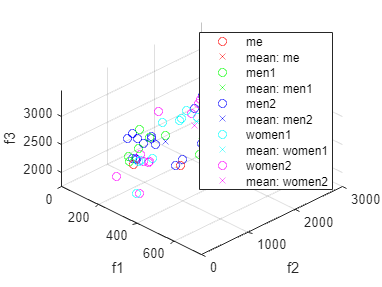

%% opc. (3) Analiza i wizualizacja danych (pod kątem osób)
uPerson = unique(personID);           % unikalne id osób
nrOfPersons = length(uPerson);        % liczba osob

colors1='rgbcmky';
figure;
hold on
% pętla po kolejnych osobach
legendstr={};k=1;
for i=1:nrOfPersons
    % UZUPELNIJ_3
    % wybór elementów, wektor logiczny
    select1 = strcmp(personID, uPerson(i));        
    
    % wybór elementów (formanty dla osoby)
    F1      = formants(select1,1);
    F2      = formants(select1,2);
    F3      = formants(select1,3);
    
    % obliczenie średniej wartości formantu dla danej osoby
    meanF1  = mean(F1);
    meanF2  = mean(F2);
    meanF3  = mean(F3);
    
    % Wizualizacja kolejnych samogłosek i ich średnich
    plot3(F1, F2, F3, ['o' colors1(i)]);
    plot3(meanF1, meanF2, meanF3, ['x' colors1(i)]);
    legendstr{k}=uPerson{i};k=k+1;
    legendstr{k}=['mean: ' uPerson{i}];k=k+1;
end
hold off
legend(legendstr)
grid on
view(45, 45);
xlabel('f1')
ylabel('f2')
zlabel('f3')

osoby ciężej rozróżnić, ale np. men2 jest dość jednorodny

## Podsumowanie

#### Rezultaty:

we wcześniejszej częsci sprawozdania

#### Analiza i wnioski:

też w odpowiednich sekcjach wcześniej

#### Pytania

- Okna czasowe redukują efekt wycieku częstotliwości, mogą pomóć z redukcją artefaktów, pomagają w redukcji wpływu wartości brzegowych

- Filtr preemfazy dzięki wzmocnieniu wysokich częstotliwości pomaga poprawić stosunek sygnału do szumu

- Spectral slope pozwala na modelowanie stresu pod jakim znajduje się mówca